# 7. Heat Transfer -interpolateTemperature

Interpolate temperature in a thermal result at arbitrary spatial locations

[`Tintrp = interpolateTemperature(thermalresults,xq,yq)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.interpolatetemperature.html#d120e56023)`:`Returns the interpolated temperature value yq at the two-dimensional point specified in xq and. This syntax is valid for both steady-state and transient thermal models.

[`Tintrp = interpolateTemperature(thermalresults,xq,yq,zq)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.interpolatetemperature.html#d120e56046)`:`Returns the xq, yq, and zq specified in the temperature value interpolated at the 3-d point. This syntax is valid for both steady-state and transient thermal models.

[`Tintrp = interpolateTemperature(thermalresults,querypoints)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.interpolatetemperature.html#d120e56073)`:`返回在中的点处的内插温度值 `querypoints`。该语法对于稳态和瞬态热模型均有效。

[`Tintrp = interpolateTemperature(``___``,iT)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.interpolatetemperature.html#d120e56094)`:`returns the interpolated temperature values for the transient thermal model at times iT .

7.1**二维稳态热模型中的插值温度**

% thermalmodel = createpde('thermal');
% R1 = [3,4,-1,1,1,-1,1,1,-1,-1]';
% g = decsg(R1, 'R1', ('R1')');
% geometryFromEdges(thermalmodel,g);
% pdegplot(thermalmodel,'EdgeLabels','on')
% xlim([-1.5,1.5])
% axis equal

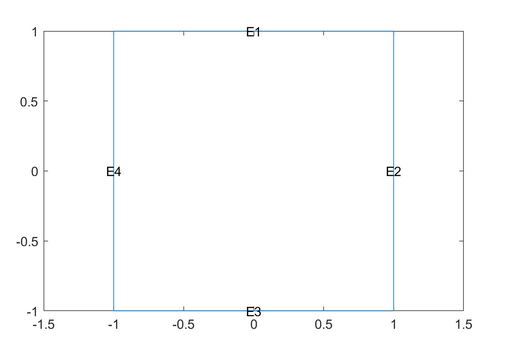

Assuming that this is an iron plate, assign a thermal conductivity of 79.5 W/(m*K). Because this is a steady-state model, you do not need to assign mass density or specific heat values.(稳态只需要设置导热系数。)

% thermalProperties(thermalmodel,'ThermalConductivity',79.5,'Face',1);

Apply a constant temperature of 300 K to the bottom of the plate (edge 3). Also, assume that the top of the plate (edge 1) is insulated, and apply convection on the two sides of the plate (edges 2 and 4).

% thermalBC(thermalmodel,'Edge',3,'Temperature',300);
% thermalBC(thermalmodel,'Edge',1,'HeatFlux',0);
% thermalBC(thermalmodel,'Edge',[2,4],...
%                        'ConvectionCoefficient',25,...
%                        'AmbientTemperature',50);

Mesh the geometry and solve the problem.

% generateMesh(thermalmodel);
% results = solve(thermalmodel)
% figure;
% pdeplot(thermalmodel,'XYData',results.Temperature,...
%                      'Contour','on','ColorMap','hot');

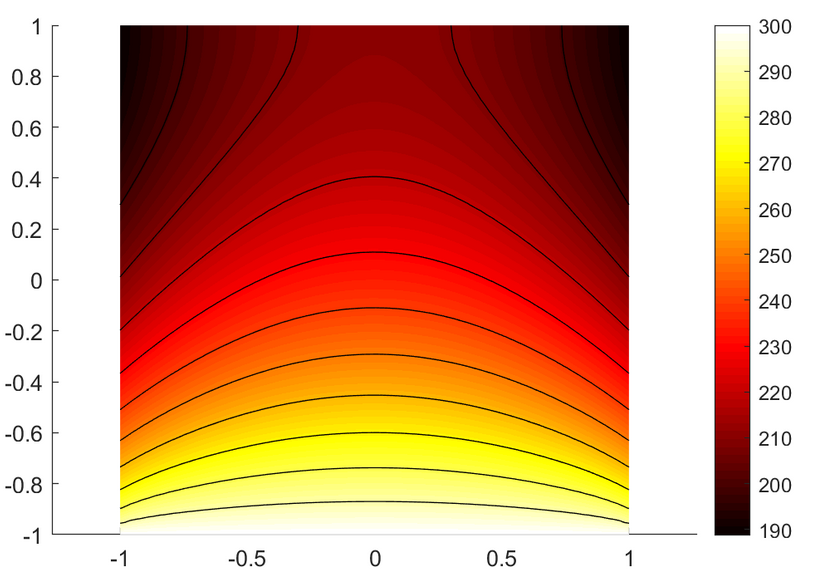

Interpolate the generated temperature into the overlay geometry，for `x` and `y` from `-0.5` to `0.5`.（查看中间一小块的温度）

% v = linspace(-0.5,0.5,11);
% [X,Y] = meshgrid(v);
% 
% Tintrp = interpolateTemperature(results,X,Y);

Reshape the `Tintrp` vector and plot the resulting temperatures.

% Tintrp = reshape(Tintrp,size(X));
% 
% figure
% contourf(X,Y,Tintrp)
% colormap(hot)
% colorbar

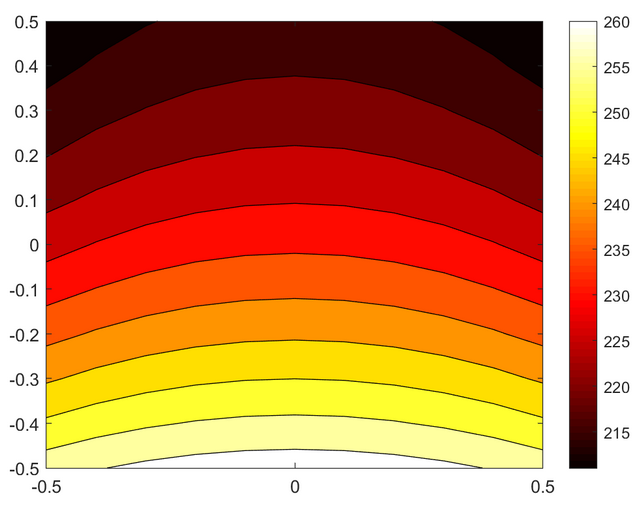

【Alternatively, you can specify the grid by using a matrix of query points.

`querypoints = [X(:),Y(:)]';`

`Tintrp = interpolateTemperature(results,querypoints);`】

7.2 **Interpolate Temperature for a 3-D Steady-State Thermal Model**

% thermalmodel = createpde('thermal');
% importGeometry(thermalmodel,'C:\Users\ZGY\Desktop\structure_heat_matlab\11.stl'); 
% pdegplot(thermalmodel,'FaceLabel','on','FaceAlpha',0.5)
% title('Copper block, cm')
% axis equal

Assuming that this is a copper block, the thermal conductivity of the block is approximately 4 W/(cm*K).

% thermalProperties(thermalmodel,'ThermalConductivity',4);

Apply a constant temperature of 373 K to the left side of the block (4) and a constant temperature of 573 K at the right side of the block.

% thermalBC(thermalmodel,'Face',4,'Temperature',373);
% thermalBC(thermalmodel,'Face',5,'Temperature',573);

Apply a heat flux boundary condition to the bottom of the block.

% thermalBC(thermalmodel,'Face',2,'HeatFlux',-20);

MESH

% generateMesh(thermalmodel);
% thermalresults = solve(thermalmodel)
% figure;
% pdeplot3D(thermalmodel,'ColorMapData',thermalresults.Temperature)

Create a grid specified by `x`, `y`, and `z` coordinates and interpolate temperatures to the grid.

% [X,Y,Z] = meshgrid(-20:0.5:20,-20:0.5:20,0:0.5:40);
% 
% Tintrp = interpolateTemperature(thermalresults,X,Y,Z);

Create a contour slice plot for fixed values of the `y` coordinate.

% figure
% 
% Tintrp = reshape(Tintrp,size(X));
% 
% contourslice(X,Y,Z,Tintrp,[],[-20:0.5:20],[])
% xlabel('x')
% ylabel('y')
% zlabel('z')
% % xlim([1,30])
% % ylim([1,20])
% % zlim([1,50])
% axis equal
% view(-50,22)
% colorbar

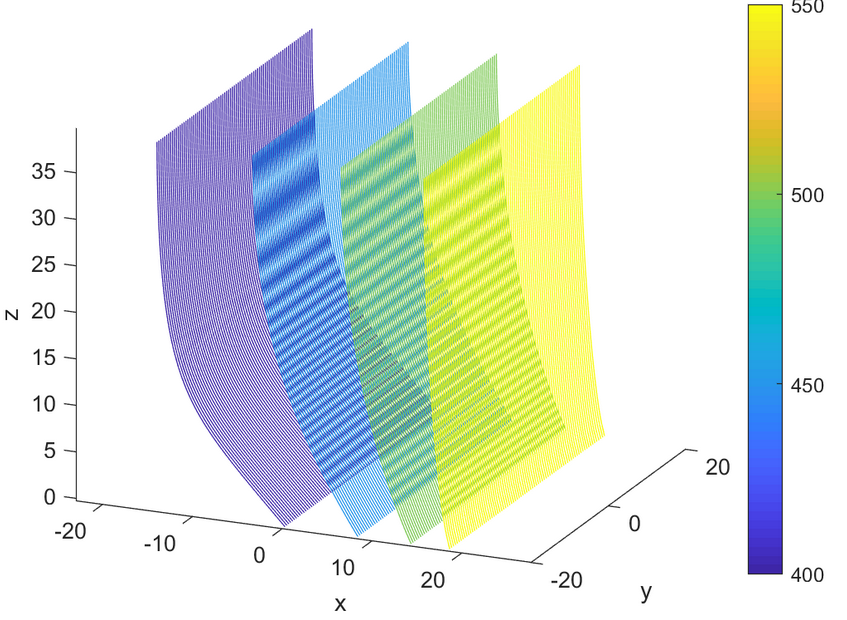

7.3 **Temperatures for a Transient Thermal Model on a Square**

Solve a 2-D transient heat transfer problem on a square domain and compute temperatures at the convective boundary.

Create a transient thermal model for this problem.

thermalmodel = createpde('thermal','transient');

Create the geometry and include it in the model.

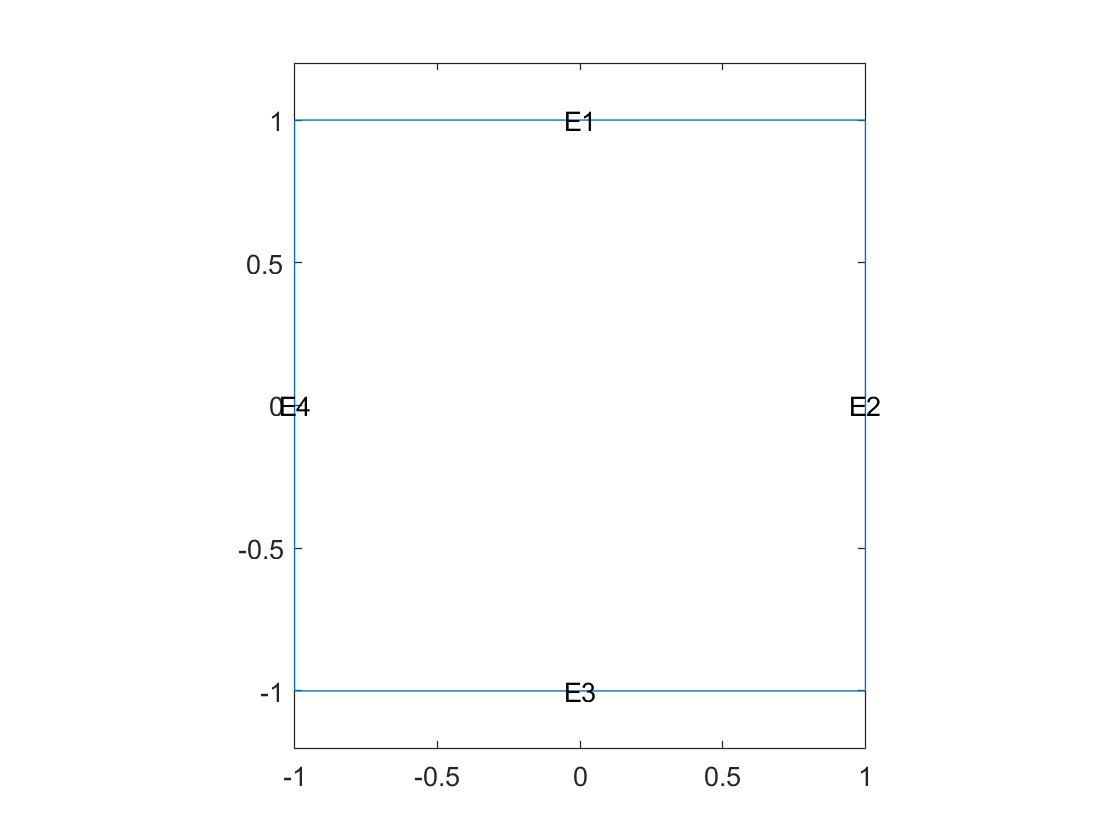

g = @squareg;
geometryFromEdges(thermalmodel,g);
pdegplot(thermalmodel,'EdgeLabels','on')
xlim([-1.2,1.2])
ylim([-1.2,1.2])
axis equal

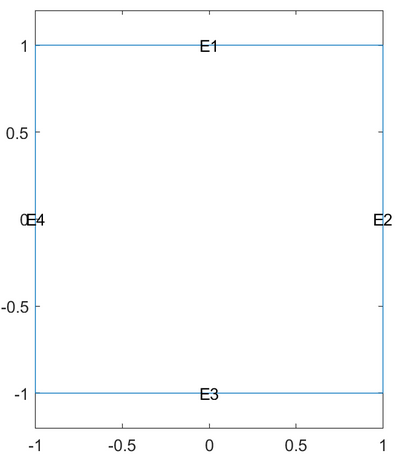

Assign the following thermal properties:

- Thermal conductivity is 100 W/(m*C)

- Mass density is 7800 kg/m^3

- Specific heat is 500 J/(kg*C)

thermalProperties(thermalmodel,'ThermalConductivity',100,...
                               'MassDensity',7800,...
                               'SpecificHeat',500);

Apply insulated boundary conditions on three edges and the free convection boundary condition on the right edge.

thermalBC(thermalmodel,'Edge',[1,3,4],'HeatFlux',0);
thermalBC(thermalmodel,'Edge',2,...
                       'ConvectionCoefficient',5000,...
                       'AmbientTemperature',25);

Set the initial conditions: uniform room temperature across domain and higher temperature on the left edge.

thermalIC(thermalmodel,25);
thermalIC(thermalmodel,100,'Edge',4);

Generate a mesh and solve the problem using `0:1000:200000` as a vector of times.

generateMesh(thermalmodel);
tlist = 0:1000:200000;
thermalresults = solve(thermalmodel,tlist)

thermalresults =   TransientThermalResults - 属性:

      Temperature: [1541×201 double]
    SolutionTimes: [1×201 double]
       XGradients: [1541×201 double]
       YGradients: [1541×201 double]
       ZGradients: []
             Mesh: [1×1 FEMesh]


在对流边界处定义一条线，并计算该线的温度梯度。

X = -1:0.1:1

X =    -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


Y = ones(size(X))%So xq, yq, and (if present) zq must have the same number of entries. 

Y =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



Tintrp = interpolateTemperature(thermalresults,X,Y,1:length(tlist))

Tintrp =   100.0000   28.9115   27.8317   27.3361   27.0378   26.8286   26.6738   26.5557   26.4593   26.3771   26.3074   26.2461   26.1930   26.1464   26.1056   26.0694   26.0365   26.0056   25.9781   25.9528   25.9287   25.9050   25.8840   25.8640   25.8447   25.8262   25.8091   25.7928   25.7772   25.7623   25.7481   25.7345   25.7214   25.7081   25.6951   25.6825   25.6704   25.6587   25.6475   25.6367   25.6263   25.6165   25.6070   25.5971   25.5873   25.5777   25.5685   25.5594   25.5506   25.5421
   19.0000   28.5412   27.6942   27.2605   26.9875   26.7930   26.6467   26.5338   26.4410   26.3618   26.2944   26.2351   26.1833   26.1379   26.0979   26.0624   26.0300   25.9997   25.9726   25.9477   25.9238   25.9006   25.8798   25.8601   25.8411   25.8228   25.8059   25.7897   25.7743   25.7595   25.7454   25.7319   25.7189   25.7057   25.6928   25.6803   25.6682   25.6566   25.6455   25.6347   25.6244   25.6146   25.6052   25.5953   25.5855   25.5760   25.5668   25.5577   25.5490

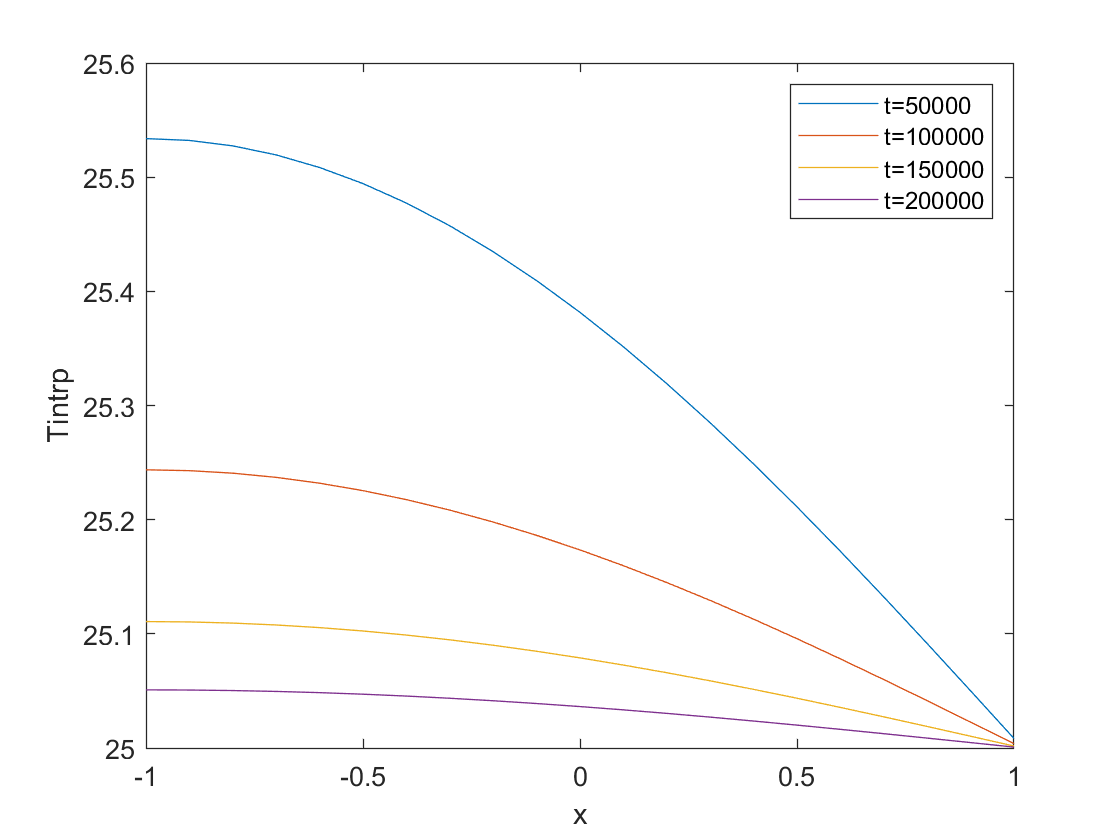

figure
t = [51:50:201];
for i = t
  p(i) = plot(X,Tintrp(:,i),'DisplayName', strcat('t=', num2str(tlist(i))));
  hold on
end
legend(p(t))
xlabel('x')
ylabel('Tintrp')